% Read data from file
fid = fopen('.\Data\ev_dif\f4.txt', 'r'); %这样读入
if fid == -1
    error('File data.txt not found. Please ensure the file exists.');
end
data = fread(fid, '*char')';
fclose(fid);

% Extract all RX Timestamps
rx_pattern = 'RX Timestamp: (\d+)';
rx_matches = regexp(data, rx_pattern, 'tokens');
if isempty(rx_matches)
    error('No RX Timestamps found in the data.');
end
%这里的rx_matches是返回所有匹配rx_pattern的数组、
rx_timestamps = zeros(length(rx_matches), 1);
for i = 1:length(rx_matches)
    rx_timestamps(i) = str2double(rx_matches{i}{1});
end
rx_timestamps

rx_timestamps = 1.0e+12 *

    0.4865
    0.4897
    0.6306
    0.6338
    0.7748
    0.7780
    0.9189
    0.9221
    1.0631
    1.0663


% Extract all Clock Offset Hz values
co_pattern = 'Clock Offset: ([\d\.]+) Hz';
co_matches = regexp(data, co_pattern, 'tokens');
if isempty(co_matches)
    error('No Clock Offset values found in the data.');
end
clock_offsets = zeros(length(co_matches), 1);
for i = 1:length(co_matches)
    clock_offsets(i) = str2double(co_matches{i}{1});
end

% Check if number of RX Timestamps and Clock Offsets are equal
if length(rx_timestamps) ~= length(clock_offsets)
    error('Number of RX Timestamps and Clock Offsets do not match.');
end

% For every two consecutive packets, form a round
num_rounds = floor(length(rx_timestamps) / 2);
if num_rounds == 0
    error('Insufficient data for rounds.至少需要两个数据包。');
end
aod_errors = zeros(1, num_rounds);
test_time = zeros(1,num_rounds); %这是用来记录时间戳间隔的
for i = 1:num_rounds
    idx1 = 2*i - 1;
    idx2 = 2*i;
    T1 = rx_timestamps(idx1);
    T2 = rx_timestamps(idx2);
    CFO = clock_offsets(idx1); % 使用每轮第一个数据包的Clock Offset
    
    delta_t = (T2 - T1) / 1e12 ; % 转换为秒
    test_time(i) = delta_t;
    aod_errors(i) = 2 * pi * delta_t * CFO; % 计算AOD_error
end

% % ---------------- 新增滤波代码开始 ----------------
% 滤除绝对值大于400的AOD_error
filtered_indices = abs(aod_errors) <= 400; % 创建逻辑索引，满足条件的为1 (True)，不满足的为0 (False)
aod_errors_filtered = aod_errors(filtered_indices); % 使用逻辑索引提取需要保留的数据

% 同时，也需要过滤对应的轮次索引，以便正确绘图
round_indices_filtered = 1:num_rounds;
round_indices_filtered = round_indices_filtered(filtered_indices);

% 计算滤波后的数据轮数
num_rounds_filtered = sum(filtered_indices); % 统计逻辑索引中 True 的个数，即有效数据量
fprintf('原始数据轮数: %d\n', num_rounds);

原始数据轮数: 70


fprintf('滤波后保留的数据轮数: %d\n', num_rounds_filtered);

滤波后保留的数据轮数: 69


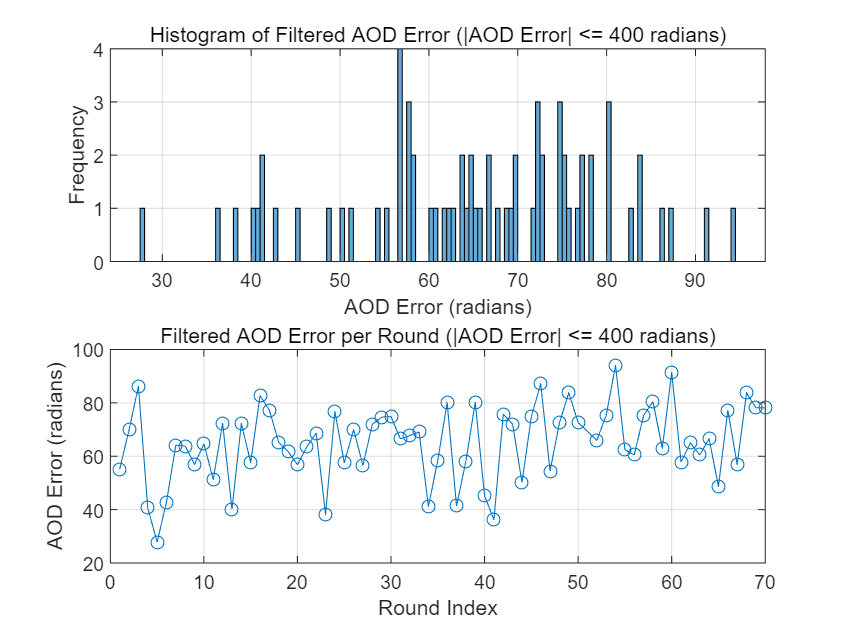

% % ---------------- 新增滤波代码结束 ----------------

% Plot histogram and line plot
figure;

subplot(2,1,1);
% 绘制滤波后的直方图
histogram(aod_errors_filtered, 'BinWidth', 0.5); % 调整BinWidth以适应数据
title('Histogram of Filtered AOD Error (|AOD Error| <= 400 radians)');
xlabel('AOD Error (radians)');
ylabel('Frequency');
grid on;

subplot(2,1,2);
% 绘制滤波后的折线图
plot(round_indices_filtered, aod_errors_filtered, '-o');
title('Filtered AOD Error per Round (|AOD Error| <= 400 radians)');
xlabel('Round Index');
ylabel('AOD Error (radians)');
grid on;


% Compute mean and standard deviation using FILTERED data
mean_aod = mean(aod_errors_filtered);
std_aod = std(aod_errors_filtered);

fprintf('Mean AOD error (filtered): %.6f radians\n', mean_aod);

Mean AOD error (filtered): 65.098150 radians


fprintf('Standard deviation of AOD error (filtered): %.6f radians\n', std_aod);

Standard deviation of AOD error (filtered): 14.149827 radians


fprintf('Mean AOD error(ppm): %.6f deg\n',0.000154*mean_aod*180/pi);

Mean AOD error(ppm): 0.574397 deg


% ... [您之后的代码保持不变] ...